xDiv = 500; yDiv = 500; zDiv = 4;
% xDiv = 300; yDiv = 300; zDiv = 4;
numEl = (xDiv-1)*(yDiv-1)*(zDiv-1);
% filename = 'exportTop600dpiColor.png';
filename = 'topLayer600dpiSimplified.png';
[layerBoundaries, topLayer] = pcbLayerImageProcessor(filename, xDiv, yDiv);

17 distinct continuous patterns detected on the surface of the PCB


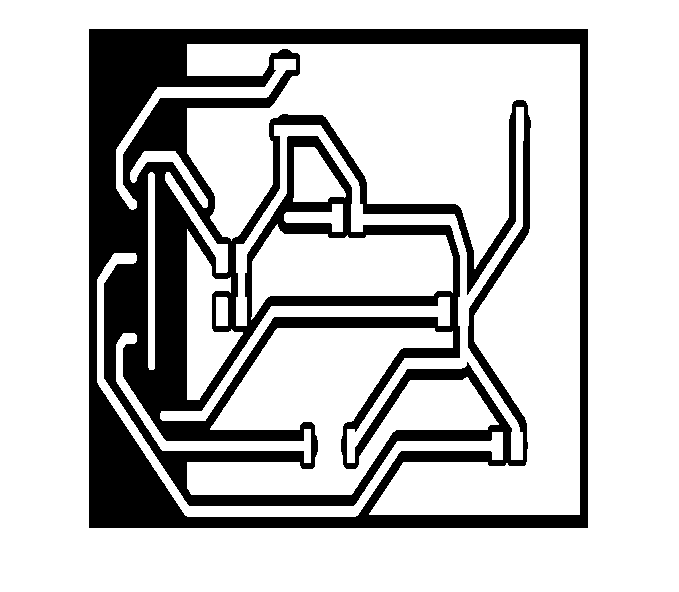

figure
imshow(topLayer)

topLayer = double(topLayer>0);
idx = reshape(0:numel(topLayer)-1, size(topLayer));
material_id = zeros(1, numEl);
mat_idx = reshape(0:numel(topLayer)-1, size(topLayer));     % temporary variable
material_id((numel(topLayer))*(zDiv-2)+1:end) = topLayer(:);
targetFile = 'material_id.txt';
fileID = fopen(targetFile, 'w');

% write the material IDs to the file:
for i = 1:length(material_id)
    fprintf(fileID, '%d ', material_id(i));
end

heatSource = [2332, 2431, 2530, 2333, 2432, 2531]+(2*numel(topLayer));

heatSource =       500334      500433      500532      500335      500434      500533


% The below is the heat source for a 500 by 500 resolution
heatSource = [63641	64140	64639	65138	65637	66136	66635	67134	67633	68132	68631	69130
            63642	64141	64640	65139	65638	66137	66636	67135	67634	68133	68632	69131
            63643	64142	64641	65140	65639	66138	66637	67136	67635	68134	68633	69132
            63644	64143	64642	65141	65640	66139	66638	67137	67636	68135	68634	69133
            63645	64144	64643	65142	65641	66140	66639	67138	67637	68136	68635	69134
            63646	64145	64644	65143	65642	66141	66640	67139	67638	68137	68636	69135
            63647	64146	64645	65144	65643	66142	66641	67140	67639	68138	68637	69136
            63648	64147	64646	65145	65644	66143	66642	67141	67640	68139	68638	69137
            63649	64148	64647	65146	65645	66144	66643	67142	67641	68140	68639	69138
            63650	64149	64648	65147	65646	66145	66644	67143	67642	68141	68640	69139
            63651	64150	64649	65148	65647	66146	66645	67144	67643	68142	68641	69140
            63652	64151	64650	65149	65648	66147	66646	67145	67644	68143	68642	69141
            63653	64152	64651	65150	65649	66148	66647	67146	67645	68144	68643	69142
            63654	64153	64652	65151	65650	66149	66648	67147	67646	68145	68644	69143
            63655	64154	64653	65152	65651	66150	66649	67148	67647	68146	68645	69144
            63656	64155	64654	65153	65652	66151	66650	67149	67648	68147	68646	69145
            63657	64156	64655	65154	65653	66152	66651	67150	67649	68148	68647	69146
            63658	64157	64656	65155	65654	66153	66652	67151	67650	68149	68648	69147
            63659	64158	64657	65156	65655	66154	66653	67152	67651	68150	68649	69148
            63660	64159	64658	65157	65656	66155	66654	67153	67652	68151	68650	69149
            63661	64160	64659	65158	65657	66156	66655	67154	67653	68152	68651	69150
            63662	64161	64660	65159	65658	66157	66656	67155	67654	68153	68652	69151
            63663	64162	64661	65160	65659	66158	66657	67156	67655	68154	68653	69152
            63664	64163	64662	65161	65660	66159	66658	67157	67656	68155	68654	69153
            63665	64164	64663	65162	65661	66160	66659	67158	67657	68156	68655	69154
            63666	64165	64664	65163	65662	66161	66660	67159	67658	68157	68656	69155
            63667	64166	64665	65164	65663	66162	66661	67160	67659	68158	68657	69156
            63668	64167	64666	65165	65664	66163	66662	67161	67660	68159	68658	69157
            63669	64168	64667	65166	65665	66164	66663	67162	67661	68160	68659	69158];
heatSource = heatSource(:)';
heatSource = heatSource + (2*numel(topLayer));
targetFileGen = 'heat_sources.txt';
fileID2 = fopen(targetFileGen, 'w');

for i = 1:length(heatSource)
    fprintf(fileID2, '%d ', heatSource(i));
end

fclose(fileID);
fclose(fileID2);